Graphs for data showing the results of 1x1 simulations which now include cell death rates. File = celtab_1x1_celldeath.mat

%%split up the data

%ptab = celtab(strcmp(celtab.mode,'proportional'),:);
%ctab = celtab(strcmp(celtab.mode,'constitutive'),:);

deathrates = sort(unique(celtab.deathrate));
example_model = celtab.model{1};
ex_v = example_model.v;
deathsperhour = deathrates * ex_v.timestep;
modes = unique(celtab.mode);

%p1 = celtabFinalBioSurfPlot(ptab(ptab.deathrate == deathrates(3),:),['Proportional, Deathrate=' num2str(deathsperhour(3)) '/h']);

%surfplots = {length(modes) * length(deathrates)};
surfdat = {length(modes) * length(deathrates)};
surfnames = {length(modes) * length(deathrates)};
idx = 1;
for m = 1:length(modes)
    mode = modes{m};
    for d = 1:length(deathrates)
        dr = deathrates(d);
        dph = deathsperhour(d);
        h = ['Deathrate = ' num2str(dph) '/h, ' mode ' enzyme'];
        surfnames{idx} = h;
        dat = celtab(strcmp(celtab.mode, mode) & celtab.deathrate == dr,:);
        surfdat{idx} = dat;
        %subplot(length(deathrates),length(modes),idx);
        %p = celtabFinalBioSurfPlot(dat,h);
        %surfplots{idx} = gca;
        idx = idx + 1;
    end
end


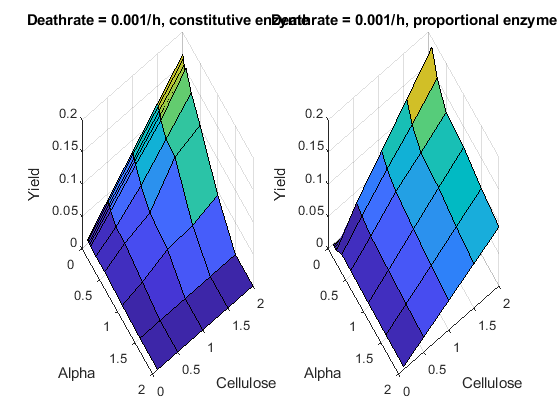

%manually plot the surfs, comparing both modes
figure
subplot(1,2,1,'replace')
celtabFinalBioSurfPlot(surfdat{1},surfnames{1});
subplot(1,2,2,'replace')
celtabFinalBioSurfPlot(surfdat{7},surfnames{7});

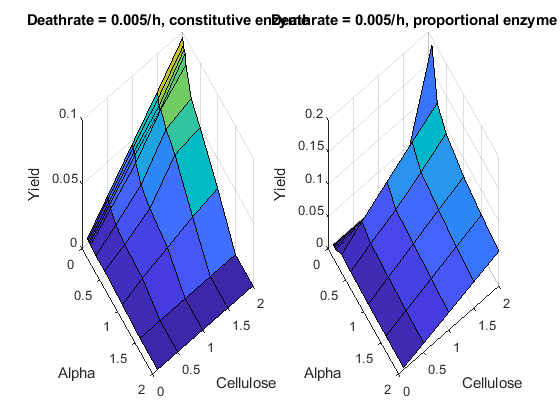


figure
subplot(1,2,1,'replace')
celtabFinalBioSurfPlot(surfdat{2},surfnames{2});
subplot(1,2,2,'replace')
celtabFinalBioSurfPlot(surfdat{8},surfnames{8});

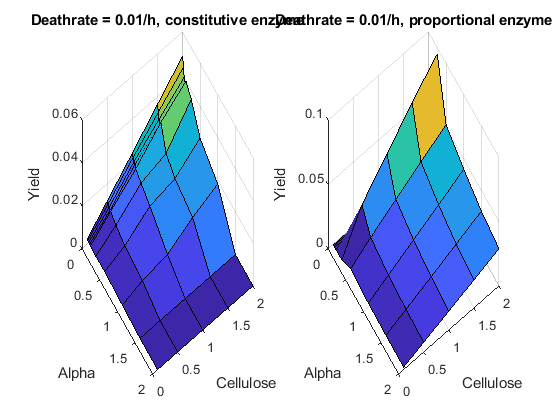


figure
subplot(1,2,1,'replace')
celtabFinalBioSurfPlot(surfdat{3},surfnames{3});
subplot(1,2,2,'replace')
celtabFinalBioSurfPlot(surfdat{9},surfnames{9});

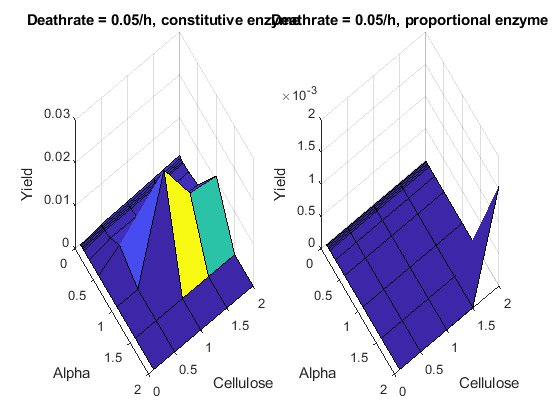


figure
subplot(1,2,1,'replace')
celtabFinalBioSurfPlot(surfdat{4},surfnames{4});
subplot(1,2,2,'replace')
celtabFinalBioSurfPlot(surfdat{10},surfnames{10});

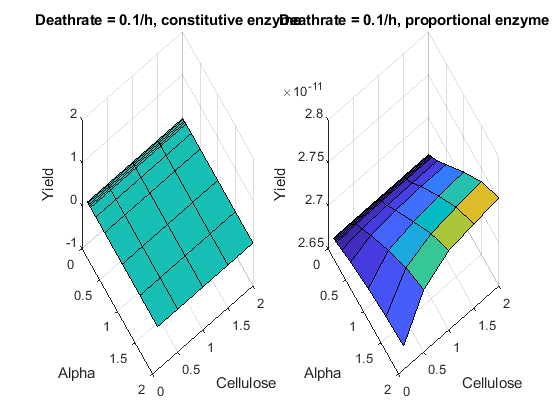


figure
subplot(1,2,1,'replace')
celtabFinalBioSurfPlot(surfdat{5},surfnames{5});
subplot(1,2,2,'replace')
celtabFinalBioSurfPlot(surfdat{11},surfnames{11});

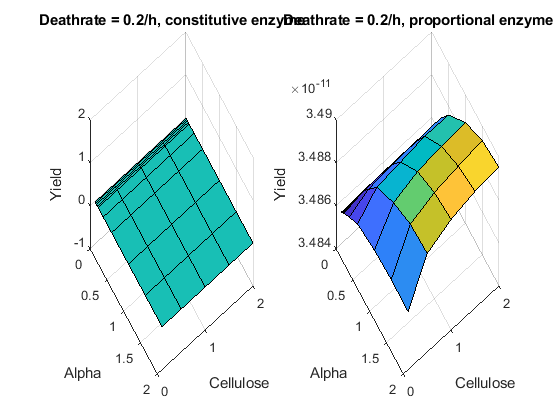


figure
subplot(1,2,1,'replace')
celtabFinalBioSurfPlot(surfdat{6},surfnames{6});
subplot(1,2,2,'replace')
celtabFinalBioSurfPlot(surfdat{12},surfnames{12});

%all constitutive plots- final biomass
figure
suptitle('Final Biomass');
subplot(2,3,1)
celtabFinalBioSurfPlot(surfdat{1},surfnames{1});
subplot(2,3,2)
celtabFinalBioSurfPlot(surfdat{2},surfnames{2})

ans =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [10×1 double]
           YData: [5×1 double]
           ZData: [5×10 double]
           CData: [5×10 double]

  Show all properties


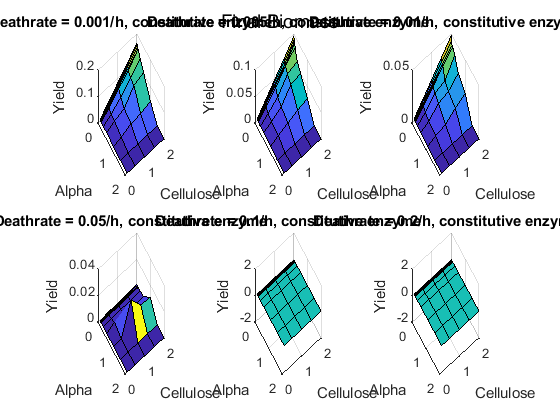

subplot(2,3,3)
celtabFinalBioSurfPlot(surfdat{3},surfnames{3});
subplot(2,3,4)
celtabFinalBioSurfPlot(surfdat{4},surfnames{4});
subplot(2,3,5)
celtabFinalBioSurfPlot(surfdat{5},surfnames{5});
subplot(2,3,6)
celtabFinalBioSurfPlot(surfdat{6},surfnames{6});

%all proportional plots- final biomass
figure
suptitle('Final Biomass')
subplot(2,3,1)
celtabFinalBioSurfPlot(surfdat{7},surfnames{7});
subplot(2,3,2)
celtabFinalBioSurfPlot(surfdat{8},surfnames{8})

ans =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [10×1 double]
           YData: [5×1 double]
           ZData: [5×10 double]
           CData: [5×10 double]

  Show all properties


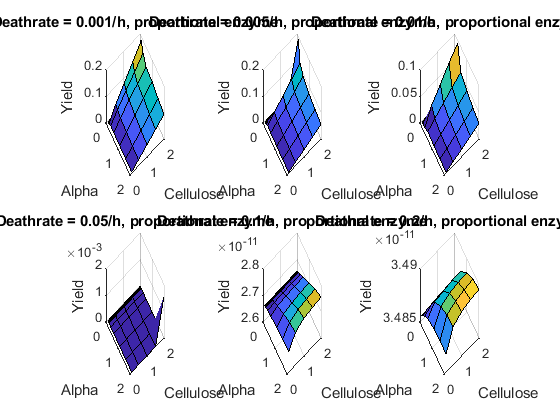

subplot(2,3,3)
celtabFinalBioSurfPlot(surfdat{9},surfnames{9});
subplot(2,3,4)
celtabFinalBioSurfPlot(surfdat{10},surfnames{10});
subplot(2,3,5)
celtabFinalBioSurfPlot(surfdat{11},surfnames{11});
subplot(2,3,6)
celtabFinalBioSurfPlot(surfdat{12},surfnames{12});

%all constitutive plots- max biomass
figure
suptitle('Maximum Biomass');
subplot(2,3,1)
celtabMaxBioSurfPlot(surfdat{1},surfnames{1});
subplot(2,3,2)
celtabMaxBioSurfPlot(surfdat{2},surfnames{2})

ans =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [10×1 double]
           YData: [5×1 double]
           ZData: [5×10 double]
           CData: [5×10 double]

  Show all properties


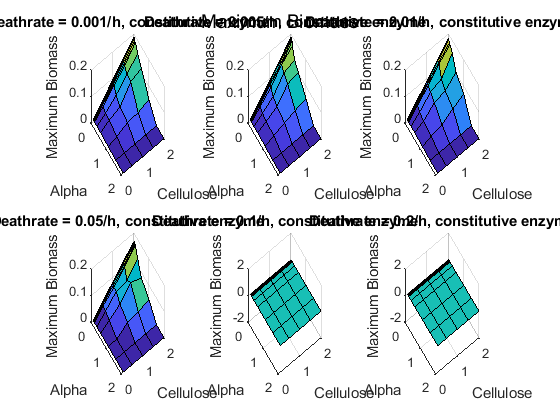

subplot(2,3,3)
celtabMaxBioSurfPlot(surfdat{3},surfnames{3});
subplot(2,3,4)
celtabMaxBioSurfPlot(surfdat{4},surfnames{4});
subplot(2,3,5)
celtabMaxBioSurfPlot(surfdat{5},surfnames{5});
subplot(2,3,6)
celtabMaxBioSurfPlot(surfdat{6},surfnames{6});

%all proportional plots- max biomass
figure
suptitle('Maximum Biomass')
subplot(2,3,1)
celtabMaxBioSurfPlot(surfdat{7},surfnames{7});
subplot(2,3,2)
celtabMaxBioSurfPlot(surfdat{8},surfnames{8})

ans =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [10×1 double]
           YData: [5×1 double]
           ZData: [5×10 double]
           CData: [5×10 double]

  Show all properties


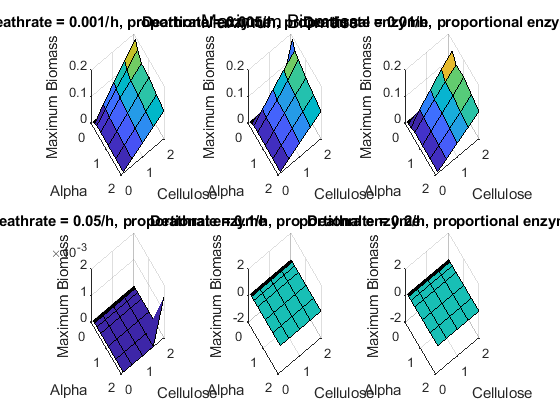

subplot(2,3,3)
celtabMaxBioSurfPlot(surfdat{9},surfnames{9});
subplot(2,3,4)
celtabMaxBioSurfPlot(surfdat{10},surfnames{10});
subplot(2,3,5)
celtabMaxBioSurfPlot(surfdat{11},surfnames{11});
subplot(2,3,6)
celtabMaxBioSurfPlot(surfdat{12},surfnames{12});

%all constitutive plots- biomass timecourse
%each subplot should show the range of alphas for a single death rate and cellulose amount
%so final superplot is 6x5
fig = figure

fig =   Figure (71) with properties:

      Number: 71
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


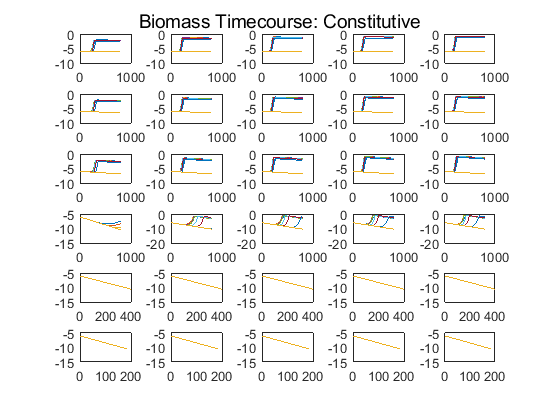

sp =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.8224 0.1237 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.8224 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.8224 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.8224 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.8224 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.8224 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.8224 0.1237 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.8224 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.8224 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.8224 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-20 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-20 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-20 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-20 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-20 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-20 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-20 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-20 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


suptitle('Biomass Timecourse: Constitutive');
xlabel(gca,'Timestep');
ylabel(gca,'log10(Biomass)');
tab = celtab(strcmp(celtab.mode,'constitutive'),:);
nd = length(deathrates);
nc = length(unique(tab.cellulose_init));
celluloses = sort(unique(tab.cellulose_init));
idx = 1;
for d = 1:nd
    for c = 1:nc
        sp = subplot(nd,nc,idx,'parent',fig)
        dat = tab(tab.deathrate == deathrates(d) & tab.cellulose_init == celluloses(c),:);
        p = plotBiomassOverTime(dat.model,sp)
        set(get(p,'title'),'visible','off');
        set(get(p,'legend'),'location','east');
        set(get(p,'legend'),'visible','off');
        set(get(p,'xlabel'),'visible','off');
        set(get(p,'ylabel'),'visible','off');
        idx = idx+1;
    end
end

%all proportional plots- biomass timecourse
%each subplot should show the range of alphas for a single death rate and cellulose amount
%so final superplot is 6x5
fig = figure

fig =   Figure (68) with properties:

      Number: 68
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


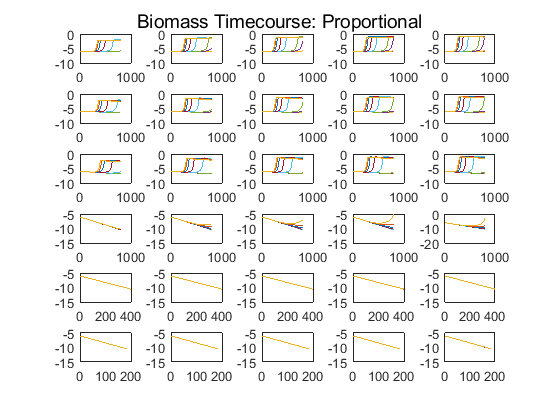

sp =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.8224 0.1237 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.8224 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.8224 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.8224 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.8224 0.1237 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.8224 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.8224 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.8224 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.8224 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.8224 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.6799 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.5374 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-20 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 1000]
             YLim: [-20 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.3950 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 400]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.2525 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6184 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


sp =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


p =   Axes (Total Biomass over Time) with properties:

             XLim: [0 200]
             YLim: [-15 -5]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7813 0.1100 0.0119 0.1026]
            Units: 'normalized'

  Show all properties


suptitle('Biomass Timecourse: Proportional');
xlabel(gca,'Timestep');
ylabel(gca,'log10(Biomass)');
tab = celtab(strcmp(celtab.mode,'proportional'),:);
nd = length(deathrates);
nc = length(unique(tab.cellulose_init));
celluloses = sort(unique(tab.cellulose_init));
idx = 1;
for d = 1:nd
    for c = 1:nc
        sp = subplot(nd,nc,idx,'parent',fig)
        dat = tab(tab.deathrate == deathrates(d) & tab.cellulose_init == celluloses(c),:);
        p = plotBiomassOverTime(dat.model,sp)
        set(get(p,'title'),'visible','off');
        set(get(p,'legend'),'location','east');
        set(get(p,'legend'),'visible','off');
        set(get(p,'xlabel'),'visible','off');
        set(get(p,'ylabel'),'visible','off');
        idx = idx+1;
    end
end

Pick a few representative parameter sets for the proportional mode and analyze them

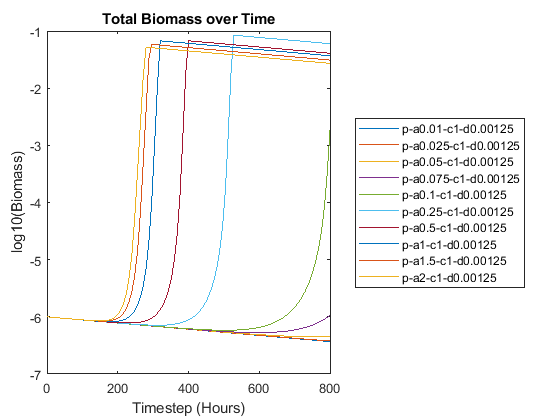

dph = 0.005;
didx = find(deathsperhour==dph,1);
dr = deathrates(didx);
cel = 1;
dat = celtab(strcmp(celtab.mode,'proportional') & celtab.deathrate == dr & celtab.cellulose_init == cel,:);
%nrows = size(dat,1);
plotBiomassOverTime(dat.model);

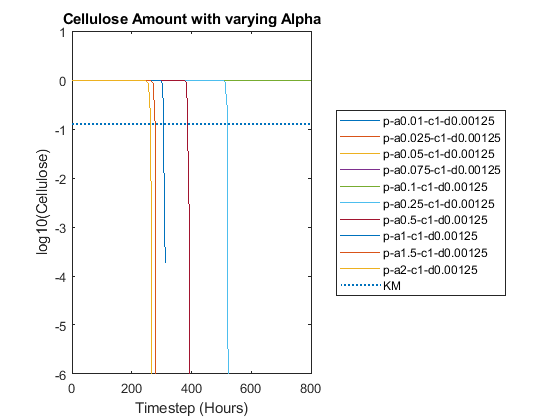

plotCelluloseTimecourse(dat.model);

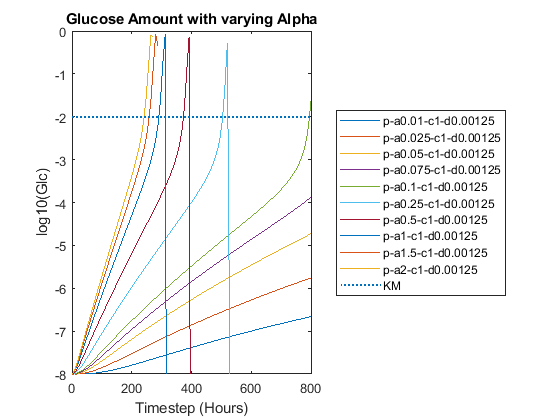

plotGlucoseTimecourse(dat.model);

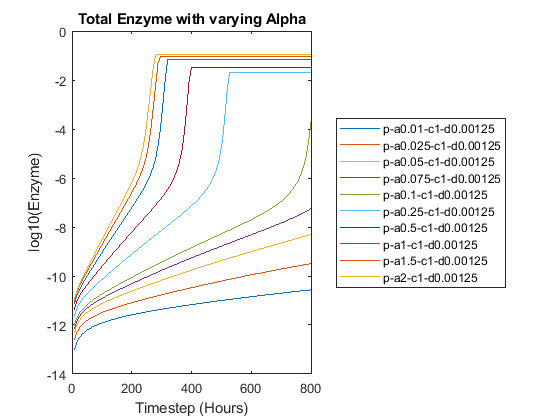

plotEnzymeTimecourse(dat.model);

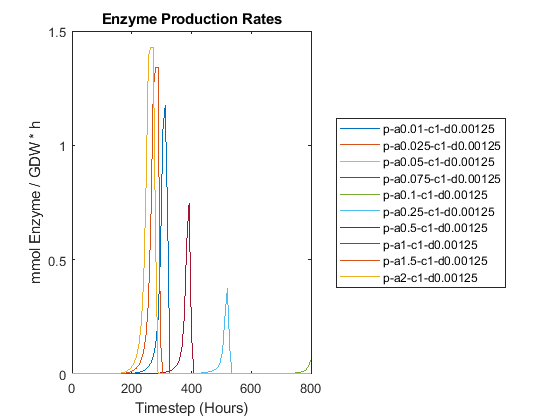

plotEnzRates(dat.model);

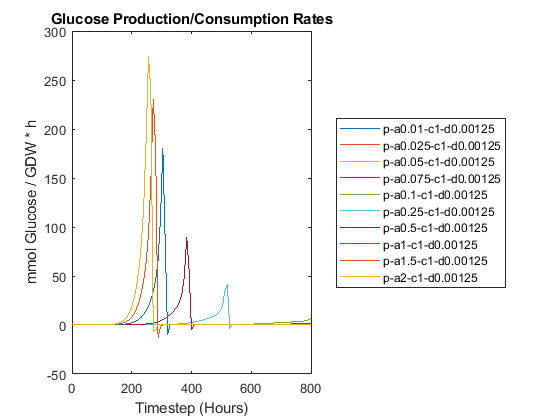

plotGlcRates(dat.model);

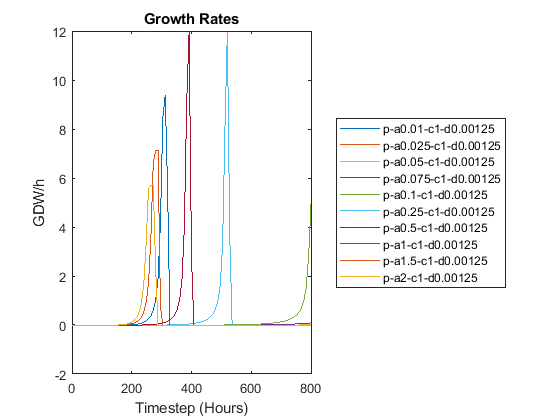

plotGrowthRates(dat.model);

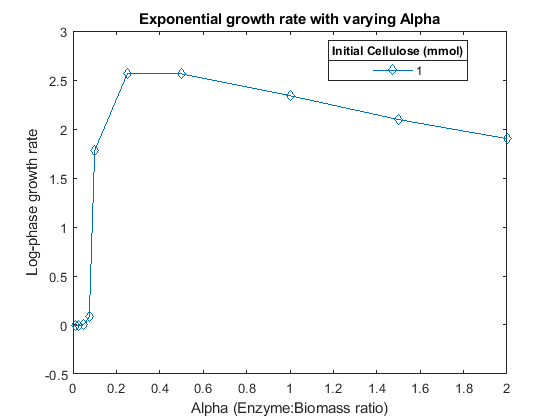

plotRAModels(dat.model);

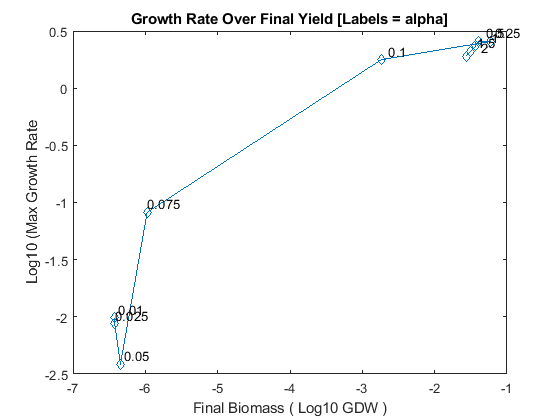

plotRateOverYield(dat.model);

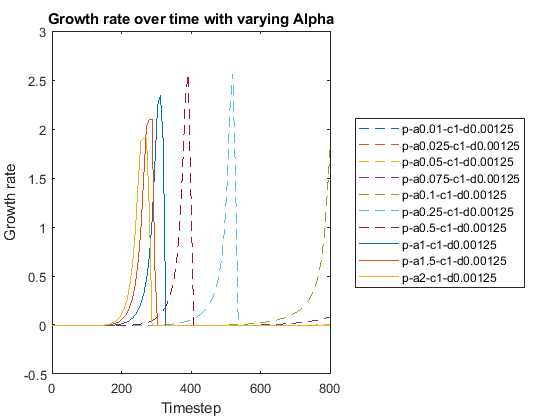

plotRates(dat.model);

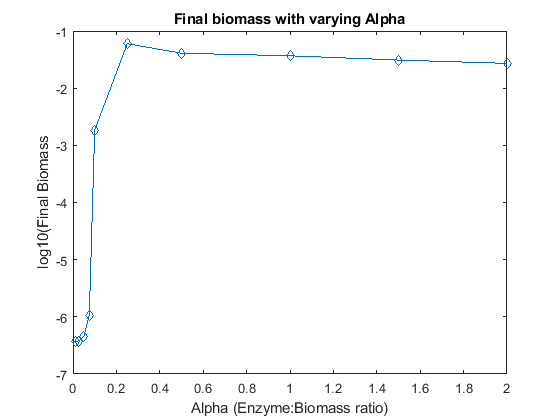

plotYAModels(dat.model);

The models at 0.005 deathrate, 1mmol cellulose appear to have a strange max biomass peak because the models with alpha < 0.25 didn't have enough time to hit their actual maximum. Let's try less cellulose... 

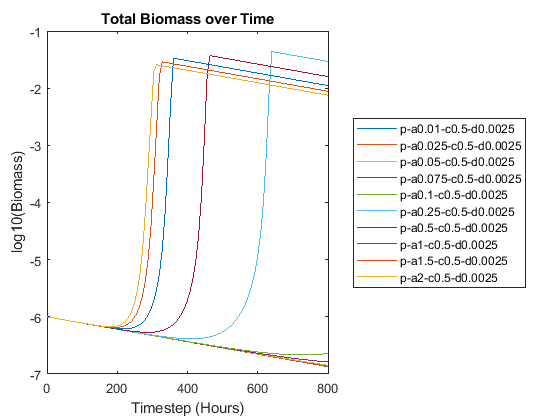

dph = 0.01;
didx = find(deathsperhour==dph,1);
dr = deathrates(didx);
cel = 0.5;
dat = celtab(strcmp(celtab.mode,'proportional') & celtab.deathrate == dr & celtab.cellulose_init == cel,:);
%nrows = size(dat,1);
plotBiomassOverTime(dat.model);

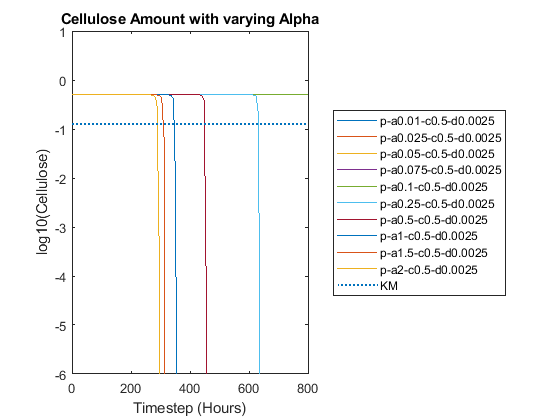

plotCelluloseTimecourse(dat.model);

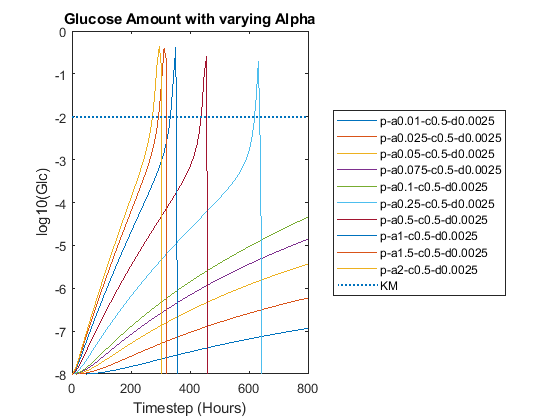

plotGlucoseTimecourse(dat.model);

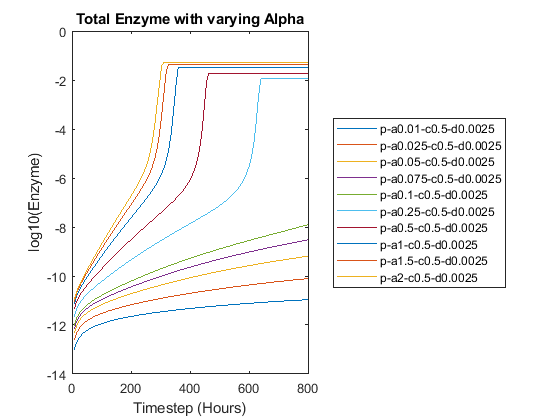

plotEnzymeTimecourse(dat.model);

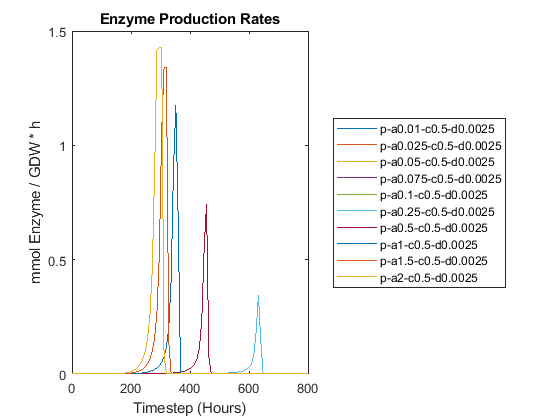

plotEnzRates(dat.model);

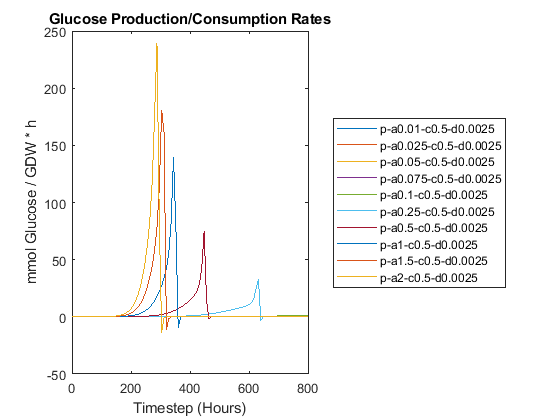

plotGlcRates(dat.model);

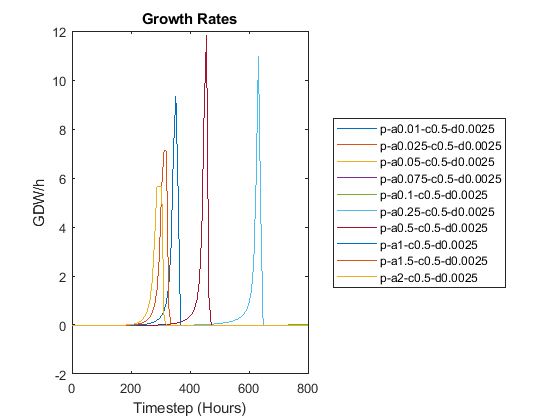

plotGrowthRates(dat.model);

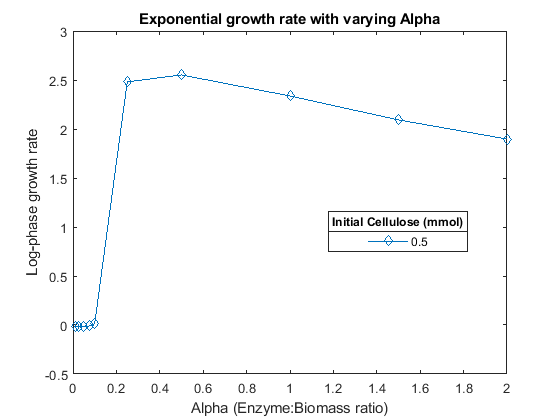

plotRAModels(dat.model);

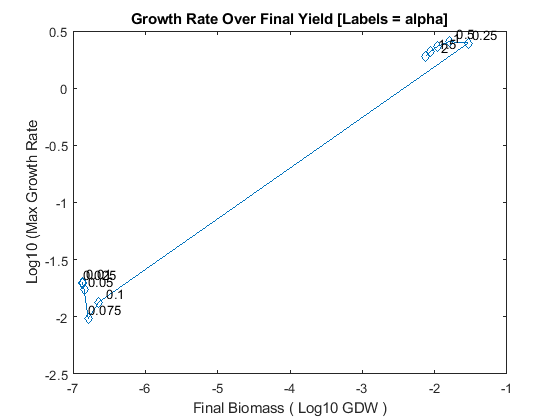

plotRateOverYield(dat.model);

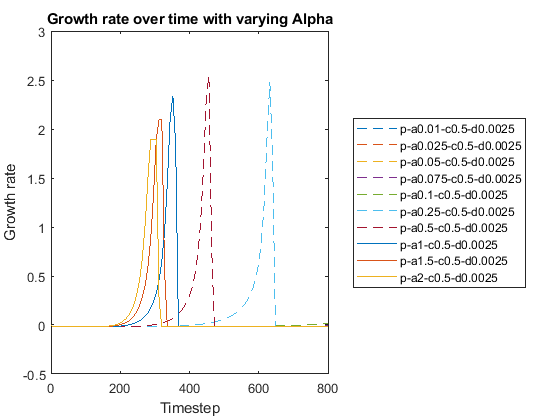

plotRates(dat.model);

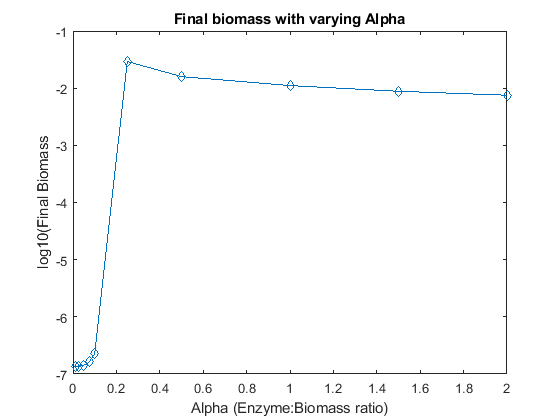

plotYAModels(dat.model);

function p = celtabFinalBioSurfPlot(tab,heading)
    yield = tab.biomass_final;
    Z = reshape(yield,[length(unique(tab.alpha)) length(unique(tab.cellulose_init))]);
    p = surf(unique(tab.alpha), unique(tab.cellulose_init), Z');
    xlabel('Alpha');
    ylabel('Cellulose');
    zlabel('Final Yield');
    title(heading);
    view([54.9000 50.0000])
end

function p = celtabMaxBioSurfPlot(tab,heading)
    yield = cellfun(@(x) max(x.biomass),tab.model);
    Z = reshape(yield,[length(unique(tab.alpha)) length(unique(tab.cellulose_init))]);
    p = surf(unique(tab.alpha), unique(tab.cellulose_init), Z');
    xlabel('Alpha');
    ylabel('Cellulose');
    zlabel('Maximum Biomass');
    title(heading);
    view([54.9000 50.0000])
end